# Testing of Combinational Algorithm against DataSet

clear all;
close all;


## Parameter Selection

PFA = 10^-3 ;
RefWindowSizeCA = 34; %reference window length for XA-CFAR
RefWindowSizeTM = 38;%ref window length for OS-CFAR and TM-CFAR
GuardCells = 2; % Number of guard cells on each

T1 = 4;
T2 = 6;


## Loading the Dataset


%% Load Data
[FileName,Path2RadarData,filter_index]=uigetfile('','Select Radar Dataset');
RadarData = load([Path2RadarData filesep FileName]);

%% Extract Range Profiles before, after Equalisation and after Notch filtering

RangeProfiles_BeforeEq = RadarData.RangeLines_BeforeEq;
RangeProfiles_AfterEq = RadarData.RangeLines_AfterEq;
RangeProfiles_AfterEqNotch = RadarData.RangeLines_AfterEQ_Notch;

%% Extract other radar parameters

 PRF_Hz = RadarData.Info.PRF_Hz;
 Bandwidth_Hz = RadarData.Info.Bandwidth_Hz;
 RangeStart_m = RadarData.Info.RangeStart_m;
 BlindRange_m = RadarData.Info.BlindRange_m;
 
[NumOfPulses,NumOfRangeBins]=size(RangeProfiles_AfterEqNotch);


## Running Dataset through CA-CFAR


% Time Domain
wrapFactor = RefWindowSizeCA/2 +GuardCells;
RangeProfiles_AfterEq=  horzcat(RangeProfiles_AfterEqNotch(:, end-wrapFactor+1:end), RangeProfiles_AfterEqNotch(:, 1:end), RangeProfiles_AfterEqNotch(:,1:wrapFactor));
[Detection_matrixCA_Time, detection_count_matrixCA_Time] = CA_CFAR_2D(RangeProfiles_AfterEq, PFA, RefWindowSizeCA, GuardCells);
Detection_matrixCA_Time = Detection_matrixCA_Time(:, wrapFactor+1:end-wrapFactor);

%Frequency Domain
Detection_matrixCA_Freq = zeros(NumOfPulses, NumOfRangeBins);
false_alarm_count_CA_Freq = zeros(1, NumOfRangeBins);

%Length of CPI
frameLength = 128;
frameNum = floor(NumOfPulses/frameLength);

%loop that runs through each CPI and implements the CA-CFAR algorithm along
%the slow-time dimesion - SAME LOOP AS SIMULATED DATASET
for n = 1:frameNum
    if n == 1
        StartIdx = 1 + (n-1)*frameLength;
        StopIdx = frameLength + (n-1)*frameLength+ wrapFactor;
        frame = RangeProfiles_AfterEqNotch(StartIdx:StopIdx, :);
        frame = vertcat(RangeProfiles_AfterEqNotch( end-wrapFactor+1:end, :), frame(1:end, :));
    elseif n == frameNum
        StartIdx = 1 + (n-1)*frameLength - wrapFactor +1;
        StopIdx = frameLength + (n-1)*frameLength;
        frame = RangeProfiles_AfterEqNotch(StartIdx:StopIdx, :);
        frame = vertcat(frame(1:end, :), RangeProfiles_AfterEqNotch(1:wrapFactor,:) );
    else
        StartIdx = 1 + (n-1)*frameLength - wrapFactor +1;
        StopIdx = frameLength + (n-1)*frameLength+ wrapFactor;
        frame = RangeProfiles_AfterEqNotch(StartIdx:StopIdx, :);
    end 

    rangeDoppler = (fft(frame, [ ], 1));
    temp_detect_matrix_transposed = zeros(NumOfRangeBins, frameLength);
    temp_detect_count_transposed = zeros(NumOfRangeBins, 1);
    [temp_detect_matrix_transposed, temp_detect_count_transposed] = CA_CFAR_2D(transpose(rangeDoppler), PFA, RefWindowSizeCA, GuardCells);
    temp_detect_matrix = transpose(temp_detect_matrix_transposed);
    temp_detect_count = transpose(temp_detect_count_transposed);

    temp_detect_matrix = temp_detect_matrix(wrapFactor+1:end-wrapFactor, :);

    columns_with_ones = any(temp_detect_matrix, 1);
    Detection_matrixCA_Freq(StartIdx:StopIdx, columns_with_ones) = 1;

    false_alarm_count_CA_Freq = false_alarm_count_CA_Freq + temp_detect_count;
    
end

%The combination of the detection algotthms to reduce false alarmsa:
% AND gate 
DetectionsCA = zeros(NumOfPulses, NumOfRangeBins);
for j = 1:NumOfRangeBins
    for i = 1: NumOfPulses
        if (Detection_matrixCA_Time(i,j) == Detection_matrixCA_Freq(i,j)) && (Detection_matrixCA_Time(i,j) == 1) 
            DetectionsCA(i,j) = 1;
        else
            DetectionsCA(i,j) = 0;
        end
    end
end



## Running Dataset through TM-CFAR

 %SAME PROCESS AS CA-CFAR BUT WITH TM-CFAR
% Time Domain
wrapFactor = RefWindowSizeCA/2 +GuardCells;
RangeProfiles_AfterEq=  horzcat(RangeProfiles_AfterEqNotch(:, end-wrapFactor+1:end), RangeProfiles_AfterEqNotch(:, 1:end), RangeProfiles_AfterEqNotch(:,1:wrapFactor));
[Detection_matrixTM_Time, detection_count_matrixTM_Time] = TM_CFAR_2D(RangeProfiles_AfterEq, PFA, RefWindowSizeTM, GuardCells, T1, T2);
Detection_matrixTM_Time = Detection_matrixTM_Time(:, wrapFactor+1:end-wrapFactor);

%Frequency Domain
Detection_matrixTM_Freq = zeros(NumOfPulses, NumOfRangeBins);
false_alarm_count_TM_Freq = zeros(1, NumOfRangeBins);

frameLength = 128;
frameNum = floor(NumOfPulses/frameLength);

for n = 1:frameNum
    if n == 1
        StartIdx = 1 + (n-1)*frameLength;
        StopIdx = frameLength + (n-1)*frameLength+ wrapFactor;
        frame = RangeProfiles_AfterEqNotch(StartIdx:StopIdx, :);
        frame = vertcat(RangeProfiles_AfterEqNotch( end-wrapFactor+1:end, :), frame(1:end, :));
    elseif n == frameNum
        StartIdx = 1 + (n-1)*frameLength - wrapFactor +1;
        StopIdx = frameLength + (n-1)*frameLength;
        frame = RangeProfiles_AfterEqNotch(StartIdx:StopIdx, :);
        frame = vertcat(frame(1:end, :), RangeProfiles_AfterEqNotch(1:wrapFactor,:) );
    else
        StartIdx = 1 + (n-1)*frameLength - wrapFactor +1;
        StopIdx = frameLength + (n-1)*frameLength+ wrapFactor;
        frame = RangeProfiles_AfterEqNotch(StartIdx:StopIdx, :);
    end 

    rangeDoppler = (fft(frame, [ ], 1));
    temp_detect_matrix_transposed = zeros(NumOfRangeBins, frameLength);
    temp_detect_count_transposed = zeros(NumOfRangeBins, 1);
    [temp_detect_matrix_transposed, temp_detect_count_transposed] = TM_CFAR_2D(transpose(rangeDoppler), PFA, RefWindowSizeTM, GuardCells, T1, T2);
    temp_detect_matrix = transpose(temp_detect_matrix_transposed);
    temp_detect_count = transpose(temp_detect_count_transposed);

    temp_detect_matrix = temp_detect_matrix(wrapFactor+1:end-wrapFactor, :);

    columns_with_ones = any(temp_detect_matrix, 1);
    Detection_matrixTM_Freq(StartIdx:StopIdx, columns_with_ones) = 1;

    false_alarm_count_TM_Freq = false_alarm_count_TM_Freq + temp_detect_count;
    
end

%The combination of the detection algotthms to reduce false alarmsa:
% AND gate 
DetectionsTM = zeros(NumOfPulses, NumOfRangeBins);
for j = 1:NumOfRangeBins
    for i = 1: NumOfPulses
        if (Detection_matrixTM_Time(i,j) == Detection_matrixTM_Freq(i,j)) && (Detection_matrixTM_Time(i,j) == 1) 
            DetectionsTM(i,j) = 1;
        else
            DetectionsTM(i,j) = 0;
        end
    end
end


## Combination of CA and TM Algorithms

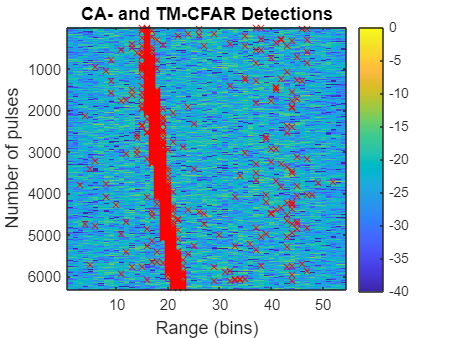


% OR Gate
Detections = zeros(NumOfPulses, NumOfRangeBins);
for j = 1:NumOfRangeBins
    for i = 1: NumOfPulses
        if (DetectionsTM(i,j) == 1) || (DetectionsCA(i,j) == 1) 
            Detections(i,j) = 1;
        else
            Detections(i,j) = 0;
        end
    end
end

%plotting
fontsize1 = 12;
[MaxRangeLine MaxIdx] = max(max(abs(RangeProfiles_AfterEqNotch)));
clims = [-40 0];
figure; axes('fontsize',fontsize1);
imagesc(20*log10(abs(RangeProfiles_AfterEqNotch)./MaxRangeLine),clims);
colorbar;
xlabel('Range (bins)','fontsize',fontsize1);
ylabel('Number of pulses','fontsize',fontsize1);
title('CA- and TM-CFAR Detections','fontsize',fontsize1);
hold on

[pulseCoord, rangeCoord] = find(Detections == 1);

% Plot 'x' at positions where matrix value is 1
scatter(rangeCoord, pulseCoord, 'rx');

## Detection Performance Test

dataset = FileName(1:2)

dataset = '01'

dataset = str2num(dataset)

dataset = 1


[numRows,numCols] = size(Detections);
Target_locations = zeros(numRows, numCols);

%loading of required dataset
if dataset == 1
    load("Target_locations_DS1.mat");
    Target_locations = Target_locations_DS1;
elseif dataset == 2
    load("Target_locations_DS2.mat");
    Target_locations = Target_locations_DS2;
elseif dataset == 3
    load("Target_locations_DS3.mat");
    Target_locations = Target_locations_DS3;
elseif dataset == 4
    load("Target_locations_DS4.mat");
    Target_locations = Target_locations_DS4;
elseif dataset == 5
    load("Target_locations_DS5.mat");
    Target_locations = Target_locations_DS5;
else 
    load("Target_locations_DS6.mat");
    Target_locations = Target_locations_DS6;
end

%detection performance test
[DetectionAccPerCell, DetectionAccPerTarget, false_alarms_perCell, missed_detections_perCell, detections_perTarget, missed_detections_perTarget, false_alarms_perTarget] = DetectionAccTest(Target_locations, Detections );
display("Detection accuracy per cell (AND): "+DetectionAccPerCell )

    "Detection accuracy per cell (AND): 86.0508"



display("Detection accuracy per target (AND): "+DetectionAccPerTarget)

    "Detection accuracy per target (AND): 93.0607"



## False Alarm Check

PFA_expected = PFA*NumOfPulses*NumOfRangeBins;
PFA_dataset = sum(false_alarms_perTarget(:));
PFA_error = (PFA_expected - PFA_dataset)/PFA_expected*100;

disp("PFA Estimates")

PFA Estimates


disp("PFA expected is " + PFA_expected)

PFA expected is 341.064


disp("*****************************************************")

*****************************************************


disp("PFA of Dataset from time domain processing is " + PFA_dataset)

PFA of Dataset from time domain processing is 176


disp("PFA error from time domain processing is is " + PFA_error + "%")

PFA error from time domain processing is is 48.3968%


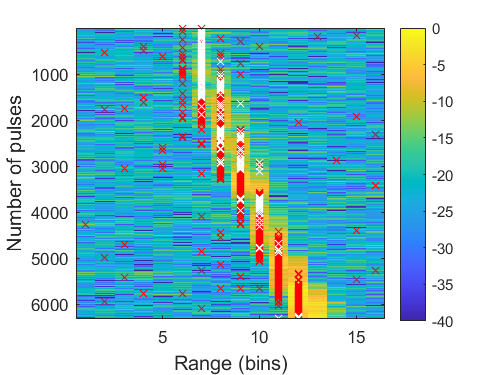


%trimming datasets to focus on target locations
if dataset == 1
    RangeProfiles_AfterEqNotch = RangeProfiles_AfterEqNotch(:,10:25);
    detections_perTarget = detections_perTarget(:,10:25);
    missed_detections_perTarget = missed_detections_perTarget(:,10:25);

end

if dataset == 2
    RangeProfiles_AfterEqNotch = RangeProfiles_AfterEqNotch(:,11:22);
    detections_perTarget = detections_perTarget(:,11:22);
    missed_detections_perTarget = missed_detections_perTarget(:,11:22);

end


if dataset == 3
    RangeProfiles_AfterEqNotch = RangeProfiles_AfterEqNotch(:,680:730);
    detections_perTarget = detections_perTarget(:,680:730);
    missed_detections_perTarget = missed_detections_perTarget(:,680:730);

end
if dataset == 4
    RangeProfiles_AfterEqNotch = RangeProfiles_AfterEqNotch(:,131:226);
    detections_perTarget = detections_perTarget(:,131:226);
    missed_detections_perTarget = missed_detections_perTarget(:,131:226);

end
if dataset == 5
    RangeProfiles_AfterEqNotch = horzcat(RangeProfiles_AfterEqNotch(:,415:476), RangeProfiles_AfterEqNotch(:,790:810));
    detections_perTarget = horzcat(detections_perTarget(:,415:476), detections_perTarget(:,790:810));
    missed_detections_perTarget = horzcat(missed_detections_perTarget(:,415:476), missed_detections_perTarget(:,790:810));

end

if dataset == 6
    RangeProfiles_AfterEqNotch = RangeProfiles_AfterEqNotch(:,1:280);
    detections_perTarget = detections_perTarget(:,1:280);
    missed_detections_perTarget = missed_detections_perTarget(:,1:280);

end
%plotting
fontsize1 = 12;
clims = [-40 0];
figure; axes('fontsize',fontsize1);
imagesc(20*log10(abs(RangeProfiles_AfterEqNotch)./MaxRangeLine),clims);
colorbar;
xlabel('Range (bins)','fontsize',fontsize1);
ylabel('Number of pulses','fontsize',fontsize1);
title('Detections and Missed Detections','fontsize',fontsize1);
hold on

%detected locations are red
[pulseCoord, rangeCoord] = find(detections_perTarget == 1);
% Plot 'x' at positions where matrix value is 1
scatter(rangeCoord, pulseCoord, 'rx');

%detected locations are white
[pulseCoord, rangeCoord] = find(missed_detections_perTarget == 1);
% Plot 'x' at positions where matrix value is 1
scatter(rangeCoord, pulseCoord, 'wx');

## False Alarm Check

PFA_expected = PFA*NumOfPulses*NumOfRangeBins;
PFA_dataset = sum(false_alarms_perTarget(:));
PFA_error = (PFA_expected - PFA_dataset)/PFA_expected*100;

disp("PFA Estimates")

PFA Estimates


disp("PFA expected is " + PFA_expected)

PFA expected is 341.064


disp("*****************************************************")

*****************************************************


disp("PFA of Dataset from time domain processing is " + PFA_dataset)

PFA of Dataset from time domain processing is 176


disp("PFA error from time domain processing is is " + PFA_error + "%")

PFA error from time domain processing is is 48.3968%


## Functions

function [Detections, detection_count] = CA_CFAR_2D(input, PFA, RefWindowSize, GuardCells)
TrainCells = (RefWindowSize)/2; % Number of training cells in reference window
[numRows,numCols] = size(input);
threshold = zeros(numRows, numCols);
Detections = zeros(numRows, numCols);
detection_count = zeros(numRows, 1);

%the CA-CFAR constant (α) 
alpha = RefWindowSize*(PFA^(-1/RefWindowSize) - 1);

%square law detector.
DataAfterPowerLawDetector = abs(input).^2 ;

%the CA-CFAR constant (α) 
startIndx = RefWindowSize/2 + GuardCells+ 1;
stopIndx = numCols - RefWindowSize/2 - GuardCells;

for i = (startIndx):(stopIndx)
    % Calculate average of reference cells in the leading and lagging windows
    reference_avg_leading = sum(DataAfterPowerLawDetector(:, i + GuardCells + 1 : i + GuardCells + RefWindowSize/2),2) ./ TrainCells;
    reference_avg_lagging = sum(DataAfterPowerLawDetector(:, i - RefWindowSize/2 - GuardCells: i - GuardCells - 1),2) ./ TrainCells;

    % Calculate threshold using scaling factor
    threshold(:, i) = alpha.*((reference_avg_leading + reference_avg_lagging) ./ 2);

    %Detection calculated
    Detections(:,i) = DataAfterPowerLawDetector(:, i) > threshold(:, i);
    detection_count = detection_count + Detections(:,i);

 
end

end




function [Detections, detection_count] = TM_CFAR_2D(input, PFA, RefWindowSize, GuardCells, T1, T2)
[numRows,numCols] = size(input);
Threshold = zeros(numRows, numCols);
Detections = zeros(numRows, numCols);
detection_count = zeros(numRows, 1);

%Square Law detector:
DataAfterPowerLawDetector = abs(input).^2 ;


% Threshold factor:
syms T p;
M1 = symprod((RefWindowSize-p)/(RefWindowSize+T*(RefWindowSize -T1 -T2) - p), p, 0, T1);
Mi = symprod(((RefWindowSize - T1 - p +1)/(RefWindowSize - T1 - T2 - p +1))/(((RefWindowSize - T1 - p +1)/(RefWindowSize - T1 - T2 - p +1))+T), p, 2, RefWindowSize - T1 - T2);
f = M1*Mi - PFA;
fh = matlabFunction(f);
root = fzero(fh, 5);
alpha = root;

%Start and Stop Indices for algorthm:
startIndx = RefWindowSize/2 + GuardCells+ 1;
stopIndx = numCols - RefWindowSize/2 - GuardCells;

% Threshold calculation:
for p = (startIndx):(stopIndx)
    % Calculate the reference cells in the leading and lagging windows
    reference_leading = (DataAfterPowerLawDetector(:, p + GuardCells + 1 : p + GuardCells + RefWindowSize/2));
    reference_lagging = (DataAfterPowerLawDetector(:, p - RefWindowSize/2 - GuardCells: p - GuardCells - 1));

    %Trimming of reference window
    reference_window = horzcat(reference_lagging, reference_leading);
    reference_window = sort(reference_window, 2);
    reference_window_trimmed = reference_window(:, 1+T1:end - T2);
    reference_window_sum = sum(reference_window_trimmed, 2);


    % Calculate threshold using scaling factor
    Threshold(:, p) = alpha.*reference_window_sum;

    %Detection calculated
    Detections(:,p) = DataAfterPowerLawDetector(:, p) > Threshold(:, p);
    detection_count = detection_count + Detections(:,p);
end
Threshold_ave = (sum(Threshold(:)))/(numCols*numRows);
end






%detection performance test
function [DetectionAccPerCell, DetectionAccPerTarget, false_alarms_perCell, missed_detections_perCell, detections_perTarget, missed_detections_perTarget, false_alarms_perTarget] = DetectionAccTest(Target_locations, Detections )

%variable creation
[numRows,numCols] = size(Target_locations);
num_detections_perCell = 0;
detections_perCell = Detections;
Target_locations_perCell = Target_locations;
missed_detections_perCell = zeros(numRows,numCols);
false_alarms_perCell = Detections;


num_detections_perTarget = 0;
detections_perTarget = Detections;
target_locations_perTarget = Target_locations;
missed_detections_perTarget = zeros(numRows,numCols);
false_alarms_perTarget = Detections;

%variable used to acount for target sidelobes so they are not assumed as
%missed detections
targetSize = 10;
% DS1 = 3
% DS2 = 3
% DS3 =10
% DS4 = 10
% DS5 = 10
% DS6 = 10

%this method does not account for target sidelobes
for i = 1:numRows
    for j = 1:numCols
        if (detections_perCell(i,j) == Target_locations_perCell(i,j))  && (detections_perCell(i,j) == 1)
            num_detections_perCell = num_detections_perCell +1;
            false_alarms_perCell(i,j) = 0;
            
        elseif Target_locations_perCell(i,j) == 1 && (detections_perCell(i,j) == 0)
            missed_detections_perCell(i,j) = 1;
        end
        
    end
   
end

%this method accounts for target sidelobes 
for i = 1:numRows
    for j = 1:numCols
        if (detections_perTarget(i,j) == target_locations_perTarget(i,j))  && (detections_perTarget(i,j) == 1)
            num_detections_perTarget = num_detections_perTarget +1;
            detections_perTarget(i, j+1:j+3) = 0; %removes target points in vicinity if the target as already been detected so it is not measured more than once
            target_locations_perTarget(i, j+1:j+targetSize) = 0; %removes ground truths in vicinity as this target has already been detected
            target_locations_perTarget(i, j-targetSize:j-1) = 0;
            false_alarms_perTarget(i, j-targetSize:j+targetSize) = 0; %removes false alarms as this target has been detected
        end
        
    end
end
for i = 1:numRows
 for j = 1:numCols
        if target_locations_perTarget(i,j) ==1 && (detections_perTarget(i,j) == 0)
            missed_detections_perTarget(i,j) = 1;
            target_locations_perTarget(i, j+1:j+targetSize) = 0;
            target_locations_perTarget(i, j-targetSize:j-1) = 0;
        end
 end
end



total_detections_perCell = sum(Target_locations(:) == 1);
total_detections_perTarget = sum(target_locations_perTarget(:) == 1);


DetectionAccPerCell = num_detections_perCell/total_detections_perCell*100;
DetectionAccPerTarget = num_detections_perTarget/total_detections_perTarget*100;

end


